clear;
clc;

# Plant

#### States Description

- x0 state: Motor velocity in rpm.

- x1 state: Motor Position in deg.

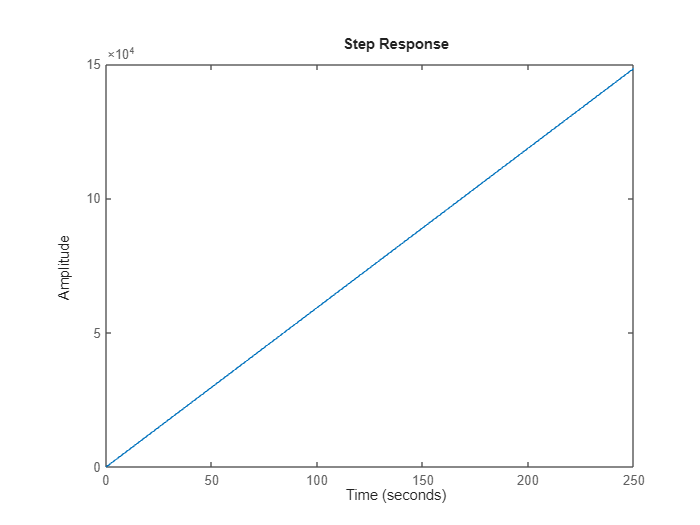

A = [-33.95 0; 360 0];
B = [55.99; 0];
C = [0 1];
D = 0;
plant_c = ss(A,B,C,D);
step(plant_c);

% Controlability verification
rank(ctrb(plant_c.A,plant_c.B))

ans = 2

## Discretization

Ts = 0.005;
plant_d = c2d(plant_c,Ts,'zoh');
% Plant poles
pole(plant_d)

ans =     1.0000
    0.8439


## Internal Model (**Two Integrators using forward approximation**)

% Internal Model Matrices
A_int_d = [1 Ts; 0 1];
B_int_d = [0; Ts];
% Augmented System
A_aug_d = [plant_d.A zeros(2,2); -B_int_d*plant_d.C A_int_d];
B_aug_d = [plant_d.B; zeros(2,1)];
C_aug_d = [plant_d.C, zeros(1,2)];
D_aug_d = 0;
aug_plant_d = ss(A_aug_d, B_aug_d, C_aug_d, D_aug_d, Ts);

# Control Design

#### Parameters

Overshoot [Mp] <= 25%, Velocity Error [Ev] = 0

The Controller is design for 50 deg movements. 

## 1. Pole Placement + IMP 

#### Pole selection

% Plant states poles (Dominant poles)
s1 = -4+0.8j;
s2 = -4-0.8j;
% Internal Model Poles
s3 = -40;
s4 = -45;
% Pole convertion to discrete using e^(Ts*s)
p = [exp(Ts*s1), exp(Ts*s2), exp(Ts*s3), exp(Ts*s4)]

p =    0.9802 + 0.0039i   0.9802 - 0.0039i   0.8187 + 0.0000i   0.7985 + 0.0000i


#### K calculation

K_pp = place(A_aug_d,B_aug_d,p);
A_cl_pp = A_aug_d-B_aug_d*K_pp;
B_cl_pp = [zeros(2,1); B_int_d];
sys_cl_pp = ss(A_cl_pp,B_cl_pp,C_aug_d,0,Ts);
pole(sys_cl_pp)

ans =    0.7985 + 0.0000i
   0.8187 + 0.0000i
   0.9802 + 0.0039i
   0.9802 - 0.0039i


#### Step Response

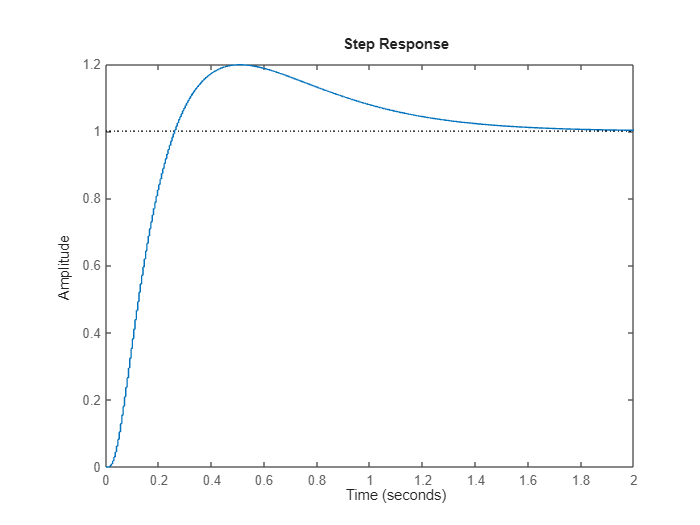

step(sys_cl_pp);

#### Final Matrices

A=plant_d.A;
B=plant_d.B;
C=plant_d.C;
A_im = A_int_d;
B_im = B_int_d;
K_x_pp = K_pp(1:2);
K_im_pp = K_pp(3:4);

## 2. Pole Placement + IMP + Ludenberg estimator 

## *3. LQR + IMP*

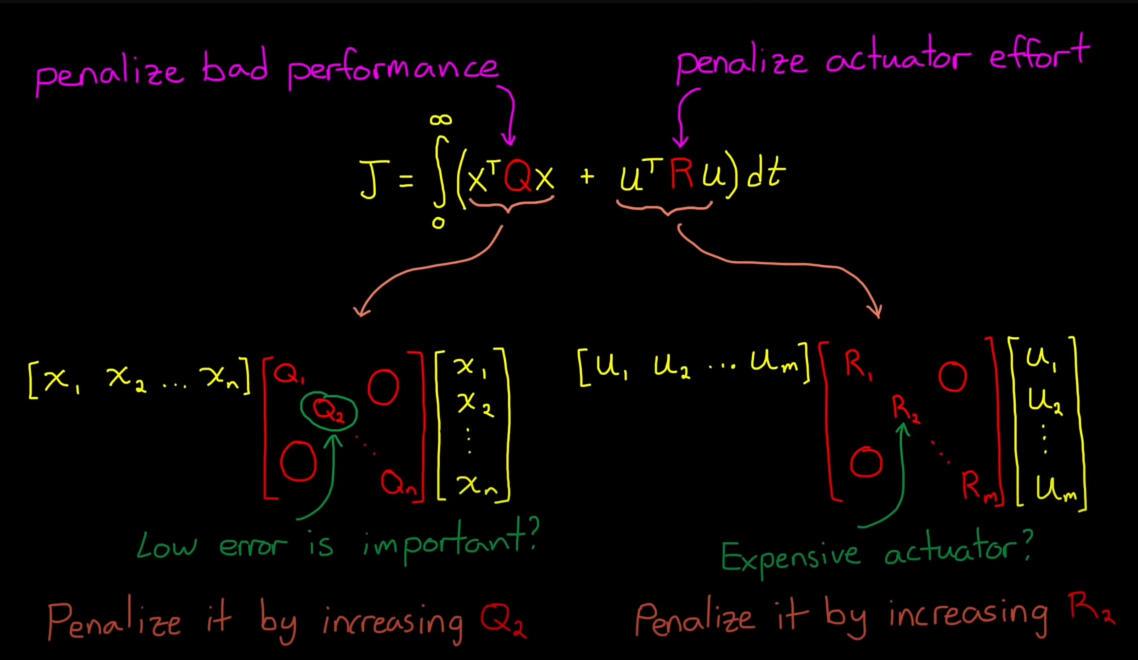

#### *Matrix Selection*

                     % Posible Effects (Conjectures)
Q = [20 0 0 0; ...   % Reward Velocity performance.
     0 0.35 0 0; ... % Reward Position performance but due to the fact that Internal model is present, the error here is zero. (Lowering makes the controller faster but increses overshoot)
     0 0 70 0; ...   % Reward stationary error performance. (Lowers stabilization time)
     0 0 0 2];       % Reward stationary speed error performance.
R = 5;               % Penalize actuator effort so reduces the risk of saturation.
Q=Q*0.2;


                     
%Q = [20 0 0 0; ...
%     0 0.35 0 0; ...
%     0 0 70 0; ...
%     0 0 0 2];
% Q=Q*0.3;
%R = 5;

#### K calculation

K_lq = dlqr(A_aug_d,B_aug_d,Q,1)

K_lq =     1.7314    0.2326   -2.7295   -1.2244


A_cl_lq = A_aug_d-B_aug_d*K_lq;
B_cl_lq = [zeros(2,1); B_int_d];
sys_cl_lq = ss(A_cl_lq,B_cl_lq,C_aug_d,0,Ts);
pole(sys_cl_lq)

ans =    0.5961 + 0.0000i
   0.7756 + 0.0000i
   0.9855 + 0.0117i
   0.9855 - 0.0117i


#### Step Response

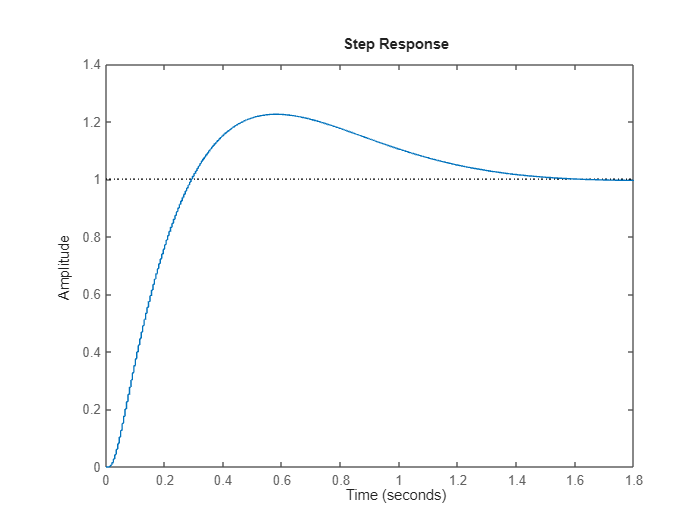

step(sys_cl_lq);

#### Final Matrices

A=plant_d.A;
B=plant_d.B;
C=plant_d.C;
A_im = A_int_d;
B_im = B_int_d;
K_x_lq = K_lq(1:2);
K_im_lq = K_lq(3:4);

## *4. LQG + IMP*